## **Soft Manipulator Actuation** 

We created a hybrid soft rigid robot with 2 revolute joint rigid links and 1 fixed joint soft link

All modes of deformation are enabled with a cubic angular strains and first order linear strains

SorosimLinks (`L1, L2, and L3`) and SorosimLinkage (S`1`) are saved in HybridSerialRobot`.mat`

load('HybridSerialRobot.mat')

To see the properties of `L1, L2, and L3`

L1

L1 =   SorosimLink with properties:

    jointtype: 'R'
     linktype: 'r'
         npie: 1
           ld: []
            L: 0.3000
           CS: 'C'
            r: @(X1)0.03
            h: []
            w: []
            a: []
            b: []
           cx: 0.1500
           gi: [4×4 double]
           gf: [4×4 double]
            E: []
          Poi: []
            G: []
          Eta: []
          Rho: 1000
           Kj: 0
           Dj: 0
            M: [6×6 double]
          n_l: 25
          n_r: 18
        color: 'r'
        alpha: 1
          CPF: 0
       PlotFn: @(g)CustomShapePlot(g)
       Lscale: 0.0947

L2

L2 =   SorosimLink with properties:

    jointtype: 'R'
     linktype: 'r'
         npie: 1
           ld: []
            L: 0.3000
           CS: 'C'
            r: @(X1)X1.*(-1.0./1.0e+2)+3.0./1.0e+2
            h: []
            w: []
            a: []
            b: []
           cx: 0.1303
           gi: [4×4 double]
           gf: [4×4 double]
            E: []
          Poi: []
            G: []
          Eta: []
          Rho: 1000
           Kj: 0
           Dj: 0
            M: [6×6 double]
          n_l: 25
          n_r: 18
        color: 'r'
        alpha: 1
          CPF: 0
       PlotFn: @(g)CustomShapePlot(g)
       Lscale: 0.0842

L3

L3 =   SorosimLink with properties:

    jointtype: 'N'
     linktype: 's'
         npie: 2
           ld: {[0.5000]}
            L: [0.5000]
           CS: 'C'
            r: {@(X1)X1.*(-1.0./1.0e+2)+1.0./5.0e+1}
            h: {[]}
            w: {[]}
            a: {[]}
            b: {[]}
           cx: []
           gi: {[4×4 double]}
           gf: {[4×4 double]}
            E: [1000000]
          Poi: [0.5000]
            G: [3.3333e+05]
          Eta: [10000]
          Rho: [1000]
           Kj: []
           Dj: []
            M: []
          n_l: [25]
          n_r: [18]
        color: 'b'
        alpha: [1]
          CPF: [0]
       PlotFn: @(g)CustomShapePlot(g)
       Lscale: [0.0856]

To see the properties of S`1`

S1

S1 =   SorosimLinkage with properties:

                      N: 3
                   ndof: 20
                   nsig: 12
                     nj: 9
                 VLinks: [1×3 SorosimLink]
              LinkIndex: [3×1 double]
                 CVRods: {3×1 cell}
                  iLpre: [3×1 double]
                  g_ini: [12×4 double]
                Z_order: 4
               OneBasis: 0
                   nCLj: 0
                   iCLA: []
                   iCLB: []
               VRodsCLj: []
                  gACLj: []
                  gBCLj: []
           CLprecompute: [1×1 struct]
                   T_BS: []
                Gravity: 1
                      G: [6×1 double]
                     np: 0
            LocalWrench: [1×0 double]
                 Fp_loc: {0×1 cell}
                 Fp_vec: {0×1 cell}
                 Fp_sig: [0×1 double]
                    CEF: 0
             UnderWater: 0
 

To see the problem definition:

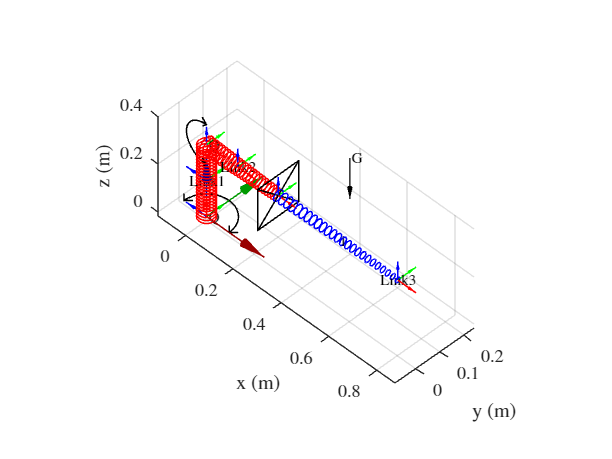

S1.plotq0

The result should be:

The hybrid robot has 2 rigid links with revolute joints and a soft body

### **Static equilibirum analysis**

For statics equilibirum analysis type:

Solving Static Equilibrium

                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          1         5.49575e+12                        1.42e+14              1
     1          2         3.11824e+12              1         5.11e+13              1
     2          3         2.22121e+10         2.3061          1.2e+13            2.5
     3          4         4.20459e+07       0.344733         9.61e+11           5.77
     4          5             179.658      0.0156566          1.6e+09           5.77
     5          6         4.38218e-09    3.56531e-05         7.96e+03           5.77
     6          7         3.33132e-19    1.80985e-10           0.0436           5.77
     7          8         3.57207e-20    1.87119e-15           0.0556           5.77

Equation solved, solver stalled.

fsolve 

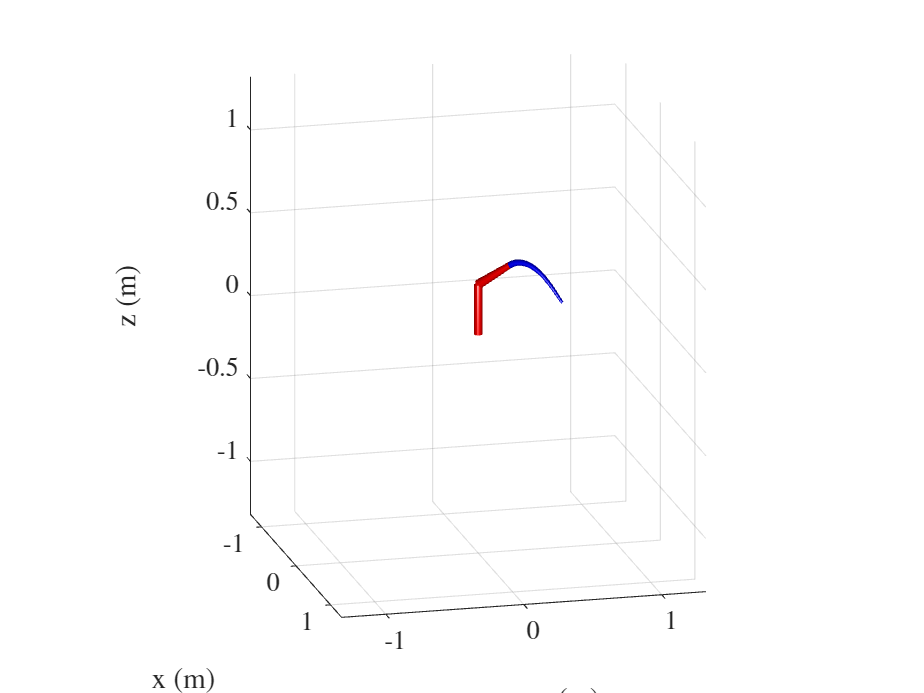

[q,u]=S1.statics;

You will be prompted to enter the actuation force in the command window. Enter the action input (joint angles) eg: pi/4, -pi/6

A dialog box will then pop up, asking for the initial guess. The user can choose the default value.

The equilibirum solution is,

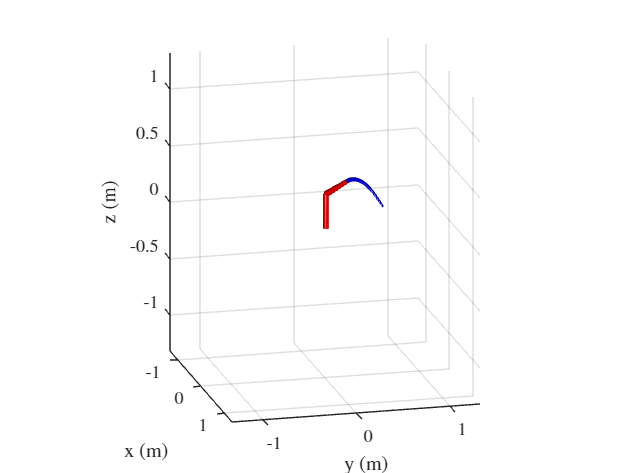

### **Dynamics**

For dynamics problem, type:

    3.5427
Elapsed time is 0.557625 seconds.


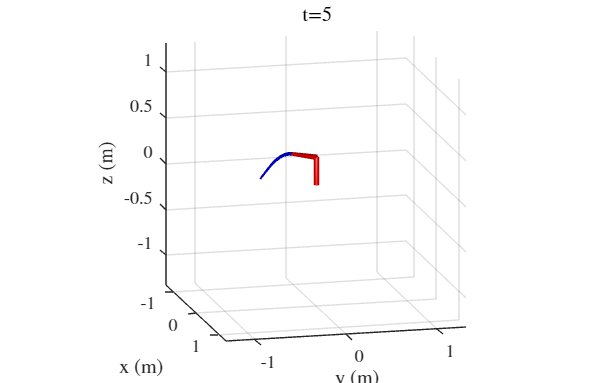

[t,qqd]=S1.dynamics;

Give actuation as functions of time.

Initial conditions of state coordinates ($$\mathbf{q_0}$$) and their derivatives ($$\mathbf{\dot{q_0}}$$) will then be asked in a dialog box. The user can also choose the time for which the simulation is run (the default value is 5 s).

The results of the dynamic simulation (`t` and `qqd`) will be saved in `DynamicsSolution.mat `in the folder from which the simulation is run.

At the end of simulation, in the dialog box that appear, choose to generate the video if needed.  **This step will take some time.** 

A video named `Dynamics.mp4` will be saved in the folder.